# Fluid descriptions

[⇦ Overview](matlab:open('./Overview.m'))

Fluid material are continuous substance composed of a very large number of particle that do not display of fixed shape. Both liquids and gases are generics type of fluids that diplay one major difference. Gas 

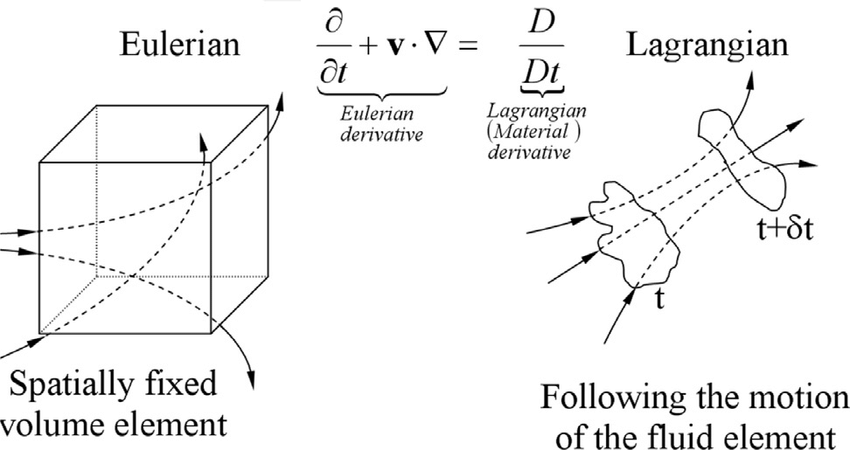

Conservation law: in an isolated system, measurable physical property does not change as the system evolves with time.

## Icon that can be used

  **Try**.

  **Pro-tip**.

** Demonstration**.

 **Reflect**.

** Application.**

## How to describe a fluid?

Let's start with tracking the position of a particle of fluid P of mass m with respect to time as it is experiencing only one force $F_p =\left\lbrack \begin{array}{c}
2*\cos \left(t\right)\\
\frac{1}{1+t}+0\ldotp 1*y
\end{array}\right\rbrack$

from mA = Sum(F)

syms x(t) y(t) m Fx(t) Fy(t) ux(t) uy(t) x0 y0
Fx(t) = 2*cos(5*t);
Fy(t) = 1/(1+t)-sin(3*t);
eqnx = m*diff(x(t), 2) == Fx(t);
ux(t) = diff(x(t), 1);
uy(t) = diff(y(t), 1);
eqny = m*diff(y(t), 2) == Fy(t);
eqns = [eqnx  eqny];

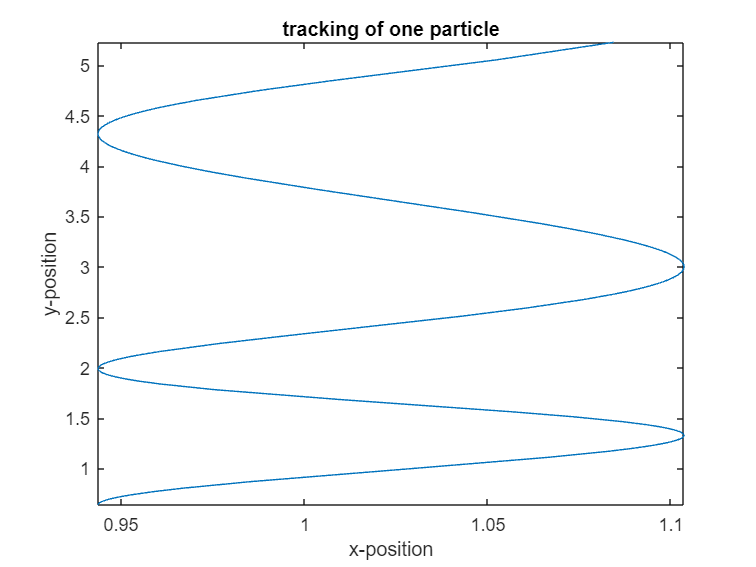

[x(t),y(t)] = dsolve(eqns, [x(0) == x0, y(0) == y0, ux(0) == 0, uy(0) == 1 ]);
xs(t) = subs(x(t),[m x0],[1 rand()]);
ys(t) = subs(y(t),[m y0],[1 rand()]);
fplot(xs(t),ys(t), [0 3])
xlabel("x-position")
ylabel("y-position")
title('tracking of one particle')

 **Reflect**. Tracking one particle would be really similar than classical solid mechanic. However fluid mechanics differ from solid mechanicis in the sense that fluid do not hold a constant shape and therefore we would need to track every (or most) particle to describe the fluid. In fact, we can define fluid parcel that are much larger than the molecule composing our gas or liquid but still very small. Let's see what it would take to track 50 of those particle with respect to time

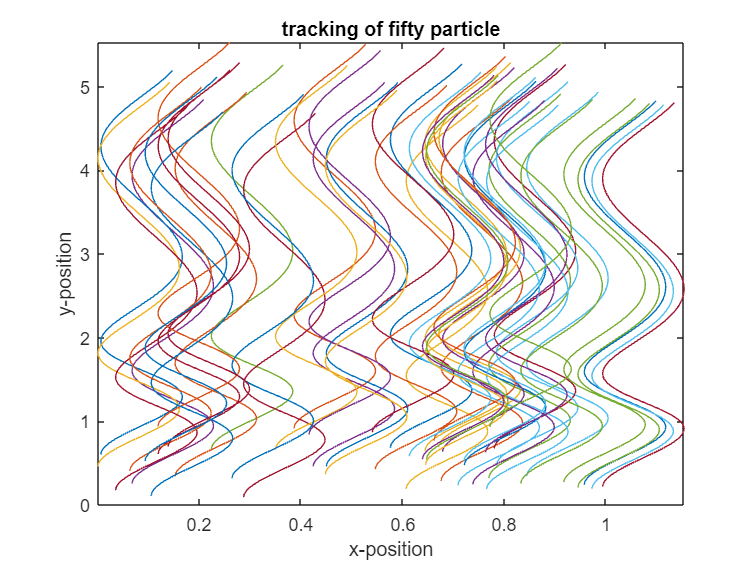

for i = 1:50
    xs(t) = subs(x(t),[m x0],[1 rand()]);
    ys(t) = subs(y(t),[m y0],[1 rand()]);
    fplot(xs(t),ys(t), [0 3])
    hold on
end
hold off
xlabel("x-position")
ylabel("y-position")
title('tracking of fifty particle')

** Application. **Weather balloon experiment are aiming at flowing in the atmosphere with the atmospheric fluid parcel and can track location, temperature, humity. etc. This type of experiment is Lagrangian by nature.

  **Pro-tip**. Lagrangian study of fluid is a powerful tool that presents limitation in XXX and is really non practical in most cases.

### Eulerian description of fluid

In Eulerian fluid description, we are tracking the change of physical properties (mass, velocities, temperatures, etc) at fixed grid point with respect to time.



% x = 0:0.1:1;
% y = 0:0.1:1;
% [xg, yg] = meshgrid(x,y);
% 
% t = 0.0;
% fx = @(x,y,t)  0.3*x+0.1*t*sqrt(x.^2+y.^2);
% fy = @(x,y,t) -0.1*x;
% 
% figure()
% hold on 
% xlim([0 1])
% ylim([0 1])
% 
% ux = fx(xg,yg,t);
% uy = fy(xg,yg,t);
% u = sqrt(ux.^2+uy.^2);
% contourf(x,y,u,256, 'LineColor', 'none')
% quiver(xg, yg, ux, uy, 'Color', 'k')

 **Reflect**. Think about how Eulerian and Lagrangian experimental setup might look like?

Eulerian: doppler, thermometer, etc.

Lagrangian: Atmospheric balloon

** Application.**

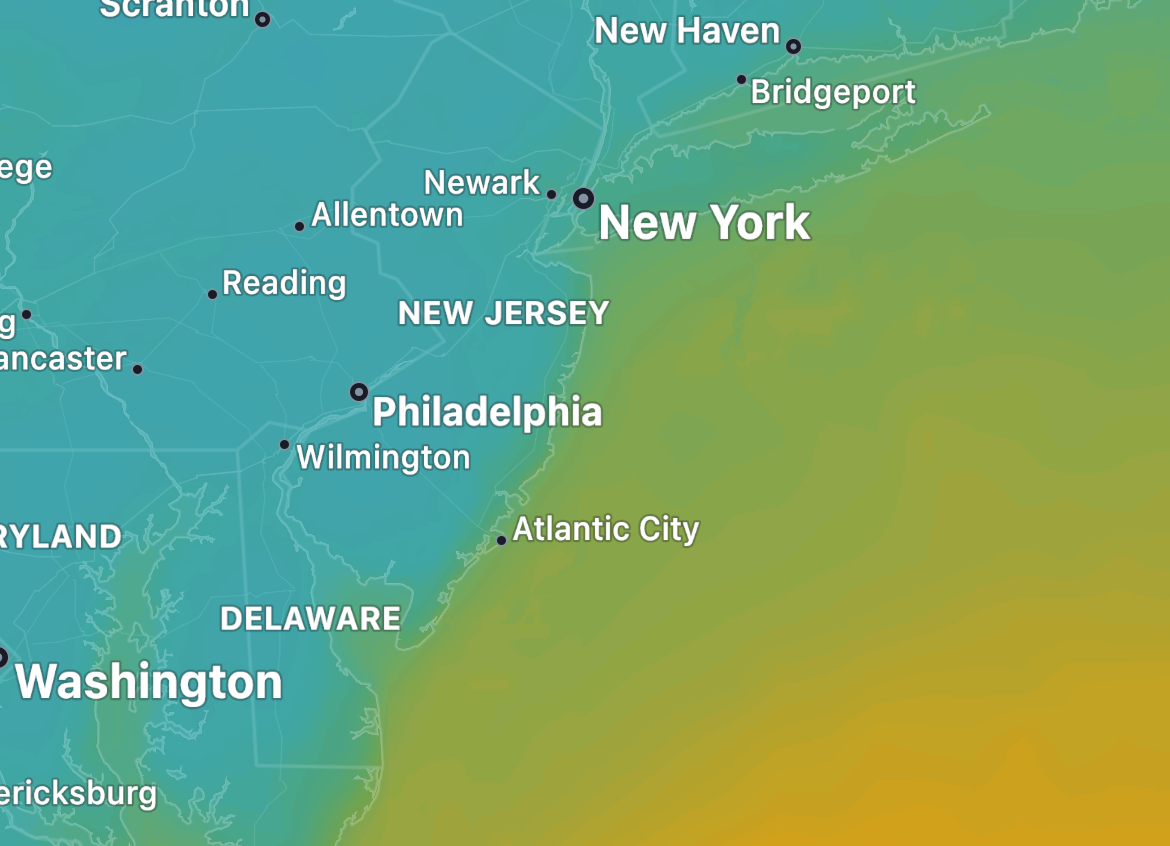

## Link in between Eulerian and Lagrangian

% x0 = [0.1 0.5];
% scatter(x0(1), x0(2), 'filled', 'SeriesIndex', 2)
% dt = 1.0;
% for i = 1:5
%     t = t + dt;
%     x0 = [x0; x0(end,:) + dt*[fx(x0(1),x0(2),t-dt) fy(x0(1),x0(2),t-dt)]];
% end
% 
% scatter(x0(:,1), x0(:,2), 'filled', 'SeriesIndex', 2);
% hold off

## Material derivative

% % scatter(0.5, 0.5, 20, 'filled', 'SeriesIndex', 2)
% % hold on
% x = 0:0.2:1;
% [X,Y] = meshgrid(x, x);
% Z = X+Y;
% pcolor(X,Y,Z, '')
% xlim([0 1])
% ylim([0 1])
% hold on
% scatter3(0.5,0.5,0.10, 20, 'filled', 'SeriesIndex',2)
% hold off
% 
% T = interp2(X,Y,Z,0.5, 0.5);
% for i = 1:10
%     X = X + 0.1;
%     T(end+1) = interp2(X,Y,Z,0.5, 0.5);
% end
% 
% plot(T)
% 

 **Reflect**. For many applications the Eulerian description is more much convenient than the Lagrangian description. 

Physical properties of the system such as temperature, mass, density, or really anything is hold on the fluid particle wether than the grid.

% syms phi(x,t) dt dx u
% 
% DPhiDt = ( phi(x+u*dt, t+dt) - phi(x,t) ) / dt
% PhiB = phi(x,t) + dt * diff(phi,t) + dx*diff(phi,x)
% PhiA = phi(x,t);
% DPhiDt = expand((PhiB - PhiA)/dt)


$$\frac{D\Phi}{Dt} = \frac{\partial \Phi}{\partial t} + {\bf u} \cdot \nabla\Phi\\

\frac{D}{Dt} \equiv \frac{\partial }{\partial t} + {\bf u} \cdot \nabla \\

$$



$$\nabla \equiv \;\left\lbrack \begin{array}{c}
\frac{\partial \;}{\partial x}\\
\frac{\partial \;}{\partial y\;}\\
\frac{\partial \;}{\partial z}
\end{array}\right\rbrack$$


## Reynolds Transport Theorem


$$\int(\nabla\cdot {\bf F})dV=\int ({\bf F}\cdot{\bf n})dS$$


1 - Derive the Reynolds transport therorem

2 - Ask to apply the theorem to mass -> conservation of mass

3 - Conservation of energy?

% 

[⇦ Return to the navigation page](matlab: OpenOverview)